if exist("wcli", "var")
    clib.webcface.wcfClose(wcli)
end

clear all;
close all;

webcfaceのロードと初期化

addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "/home/kou/projects/mech-jishupro/ik/webcface/webcfaceInterface.so"
               Libraries: ["libwebcface.so"    "libspdlog.so"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 1475909


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli)

ans = int32
0

fk, ikの初期化

% Generate robot
%robot = loadrobot("kinovaGen3","DataFormat","column");
robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

p0 = tform2trvec(getTransform(robot, q, "arm_link7_link", "base_link"));
x0 = p0(1)

x0 = 0.5084

y0 = p0(2)

y0 = -0.0300

z0 = p0(3)

z0 = 0.2976


% Define IK solver
ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
%weights = [1, 1, 1, 1, 1, 1];
endEffector = 'arm_link7_link';

target = "bullet-sim"

target = "bullet-sim"

%if target == "bullet-sim"
%    reverse = [1 1 1 1 1 1 1];
%else
%    reverse = [1 1 1 -1 1 -1 1]; % 4と6番のサーボが逆についていると思ったがそんなことはなかった
%end
reverse = [1 1 1 1 1 1 1];

use_plot = false

use_plot = logical
   0


初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qa = clib.array.webcface.wcfMultiVal(7);
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qa(j) = clib.webcface.wcfValD(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
clib.webcface.wcfFuncRun(wcli, target, "move_servo", qa)

ans = int32
0

if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end

clib.webcface.wcfFuncListen(wcli, "setDest", [4, 4, 4], 0)

ans = int32
0

clib.webcface.wcfFuncListen(wcli, "setDestDiff", [4, 4, 4], 0)

ans = int32
0

r = rateControl(5);
clib.webcface.wcfSync(wcli)

ans = int32
0

x = x0;
y = y0;
z = z0;
while true
    [ret, h] = clib.webcface.wcfFuncFetchCall(wcli, "setDest");
    if ret == 0
        x = h.args(1).as_double;
        y = h.args(2).as_double;
        z = h.args(3).as_double;
        q = ik(endEffector,trvec2tform([x y z]),weights,q);
        qa = clib.array.webcface.wcfMultiVal(7);
        for j = 1:7
            qa(j) = clib.webcface.wcfValD(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
        end
        clib.webcface.wcfFuncRun(wcli, target, "move_servo", qa)
        if use_plot
            show(robot, q, Frames="off");
            xlim([-0.4 0.6])
            ylim([-0.5 0.5])
            zlim([-0.25 0.75])
        end
        clib.webcface.wcfFuncRespond(h, clib.webcface.wcfValI(0))
    end
    [ret, h] = clib.webcface.wcfFuncFetchCall(wcli, "setDestDiff");
    if ret == 0
        dx = h.args(1).as_double;
        dy = h.args(2).as_double;
        dz = h.args(3).as_double;
        q2 = ik(endEffector,trvec2tform([x+dx y+dy z+dz]),weights,q);
        ok = true;
        for j = 1:7
            if abs(q2(j).JointPosition - q(j).JointPosition) > deg2rad(10)
                ok = false;
            end
        end
        if ok
            q = q2;
            x = x + dx;
            y = y + dy;
            z = z + dz;
            qa = clib.array.webcface.wcfMultiVal(7);
            for j = 1:7
                qa(j) = clib.webcface.wcfValD(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
            end
            clib.webcface.wcfFuncRun(wcli, target, "move_servo", qa)
            if use_plot
                show(robot, q, Frames="off");
                xlim([-0.4 0.6])
                ylim([-0.5 0.5])
                zlim([-0.25 0.75])
            end
            clib.webcface.wcfFuncRespond(h, clib.webcface.wcfValI(0))
        else
            clib.webcface.wcfFuncReject(h, "ik failed")
        end
    end
    waitfor r
end

'struct' タイプのオペランドに対して、演算子 '-' はサポートされていません。

値を入れてikを解き、送る

x = 0.46

x = 0.4600

y = -0.06

y = -0.0600

z = 0.46

z = 0.4600

q = ik(endEffector,trvec2tform([x y z]),weights,q);
qa = clib.array.webcface.wcfMultiVal(7);
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qa(j) = clib.webcface.wcfValD(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
clib.webcface.wcfFuncRun(wcli, target, "move_servo", qa)

qs = 1×7 の string 配列
    "289.2308"    "820.5102"    "215.1071"    "337.662"    "726.2967"    "436.5648"    "500"


ans = ""

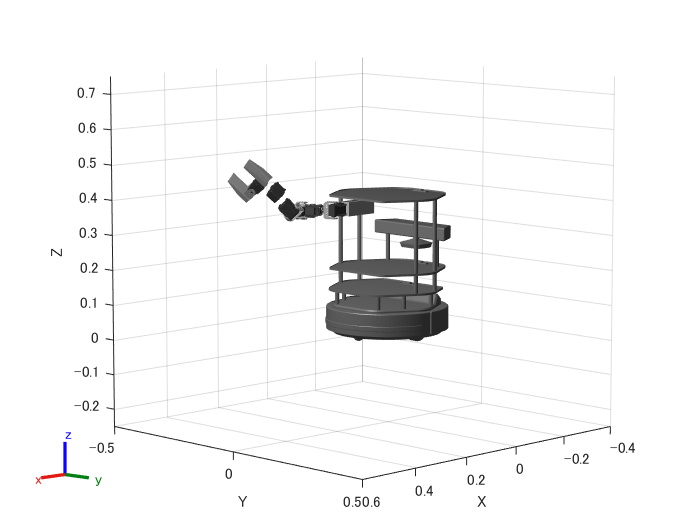

if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end

サーボをoffにする

 
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "free_servo", [])

ans = ""

 
clib.webcface.wcfClose(wcli);